|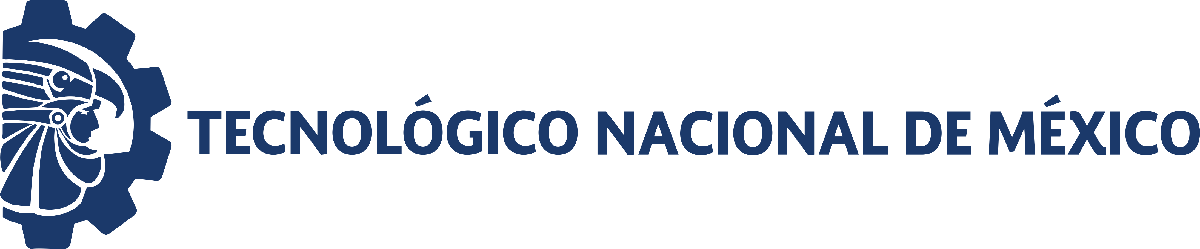                                 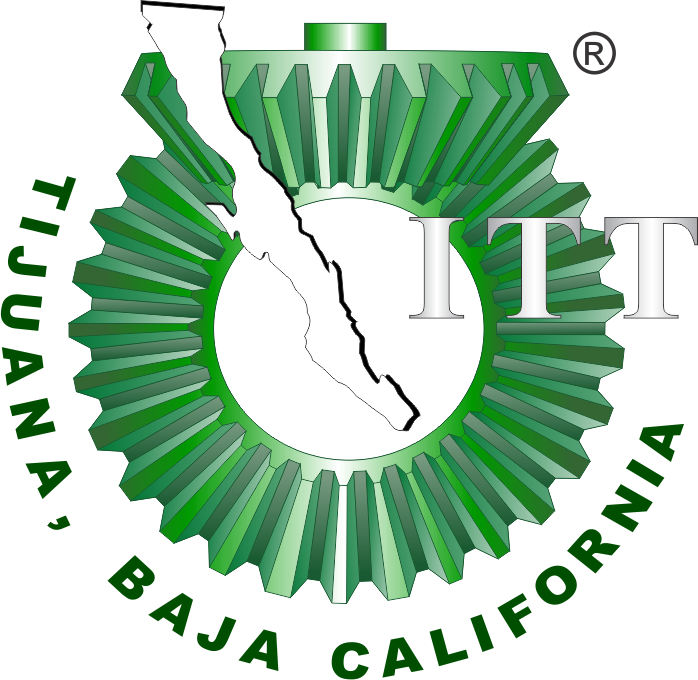

# Práctica 2: Sistema Respiratorio 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[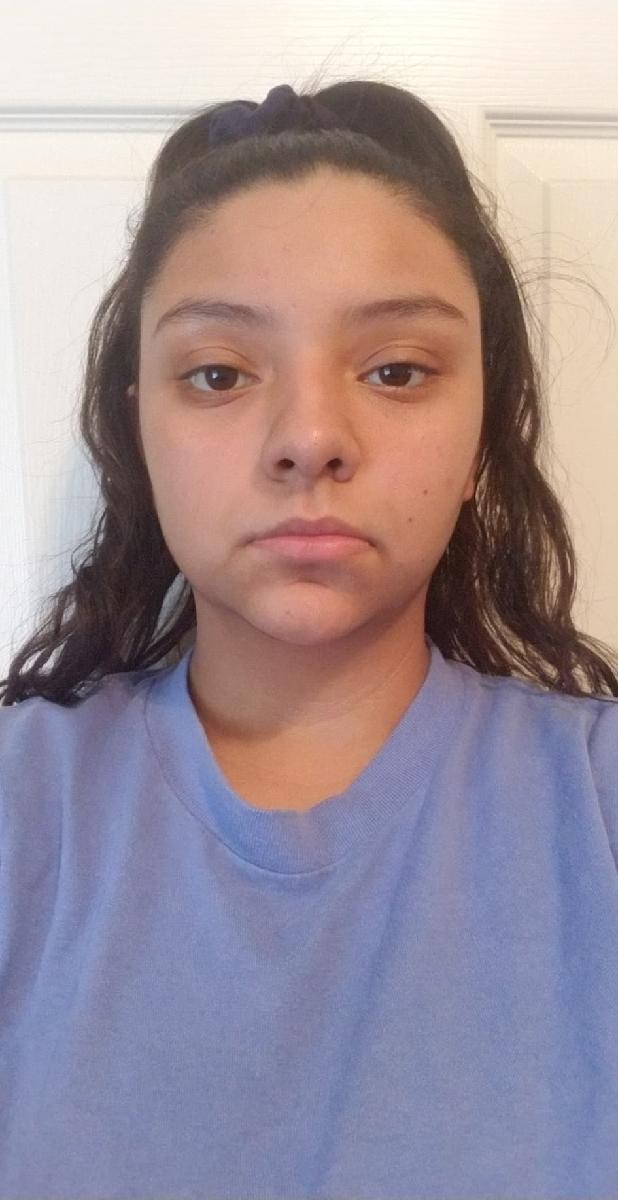]

Nombre del alumno: Jael Badillo Cruz 

Número de control: 22210409

Correo institucional:l22210409@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Labuena';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15';
parameters.MaxStep = '1E-3';
parameters.StopTime = '30';

## Rendimiento del controlador

KP = 67.7874

KI=  685.7919

kD = 0.38523

## Respiracion normal

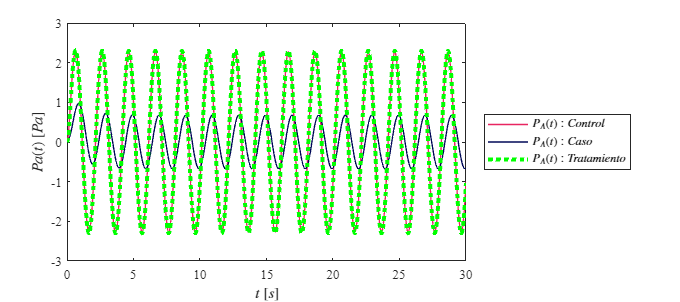

Signal = 'Respiracion normal';
set_param('Labuena/Pao(t)','sw','1');
set_param('Labuena/PID Controller','P','67.7874');
set_param('Labuena/PID Controller','I','685.7919');
set_param('Labuena/PID Controller','D','0.38523');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Respiración anormal

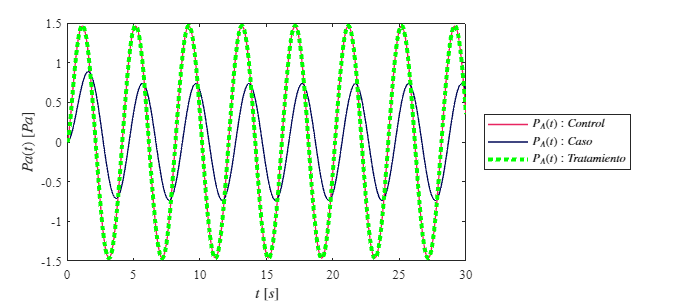

Signal = 'Respiracion Anormal';
set_param('Labuena/Pao(t)','sw','0');
set_param('Labuena/PID Controller','P','67.7874');
set_param('Labuena/PID Controller','I','685.7919');
set_param('Labuena/PID Controller','D','0.38523');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Funcion:Respuesta a las señales

function plotsignals(t,PA,Pao,PID,Signal)
set(figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,18,8])
set(gca,'FontName','Times New Roman')
fontsize(10,'points')
red = [232/255, 37/255,97/255];
blueR = [0, 9/255, 87/255];
green = [0, 255/255, 0];
hold on; grid off; box on;

plot(t,PA,'LineWidth',1,'Color',red)
plot(t,Pao,'LineWidth',1,'Color',blueR)
plot(t,PID,':','LineWidth',3,'Color',green)

  xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$Pa(t)$ $[Pa]$','Interpreter','Latex')

L = legend('$P_{A}(t): Control$', '$P_{A}(t): Caso$','$P_{A}(t): Tratamiento$');  
set(L, 'Interpreter', 'Latex', 'Location', 'EastOutside', 'Box', 'on');


end